addpath('Classes')
addpath('Simulink Models')
addpath('Functions')

%Make sure symprefs are set correctly for this script
sympref('MatrixWithSquareBrackets',true);
sympref('AbbreviateOutput', false);
sympref('FloatingPoint',true);
sympref('TypesetOutput',true);


# SISO Sliding Mode Control Research Script

%Create a variable definitions object if one does not already exist. 
if (~exist('VDefs', 'var')) 

    VDefs = Var_Defs;  %Create an object of the class Var_Defs

end 

%Create a u-joint Kinematics object if one does not already exist. 
if (~exist('UJ_Knmtcs', 'var')) 

    UJ_Knmtcs = UJ_Knmtcs(VDefs); %Create an object of the class UJ_Knmtcs
    UJ_Knmtcs.derive_all; %Run all of its derivation functions

end 

%Create a ball-plate kinematics object if one does not already exist. 
if (~exist('BP_Knmtcs', 'var')) 

    BP_Knmtcs = BP_Knmtcs(VDefs, UJ_Knmtcs); %Create an object of the class BP_Knmtcs
    BP_Knmtcs.Derive_Both; %Derive all the kinematic equations for the ball-plate system
end 

%Create a ball-plate kinetics object if one does not already exist. 
if (~exist('BP_Kinetics', 'var')) 

    BP_Kinetics = BP_Kinetics(VDefs, UJ_Knmtcs, BP_Knmtcs); %Create an object of the class BP_Kinetics
    BP_Kinetics.Derive_NL_EOMs; %Derive the nonlinear equations of motion for the ball-plate system
    BP_Kinetics.Num_Params_n_Assumptions; %Input numerical parameters and assumptions
end 


%Create a nonlinear decoupled EOMs object if one does not already exist. 
if (~exist('NL_Dcpld_EOMs', 'var')) 

    NL_Dcpld_EOMs = NL_Dcpld_EOMs(VDefs, BP_Kinetics); %Create an object of the class NL_Dcpld_EOMs
    NL_Dcpld_EOMs.Num_Params;
end

%Define a few symbolic variables to be used
syms y_1s y_2s y_dot_1s y_dot_2s y_ddot_1s y_ddot_2s lambda_1 lambda_2 S_1 S_2 S_dot_1 S_dot_2 T_max T_hat_beta T_hat_gamma K_s
 

rb_global = Num_Params(subs(VDefs.R20*[VDefs.x; VDefs.y; VDefs.z_b], VDefs.symFunVec, VDefs.symVarVec), VDefs);
vb_global = Num_Params(subs(VDefs.R20*BP_Knmtcs.vb2s, VDefs.symFunVec, VDefs.symVarVec), VDefs);
ab_global = Num_Params(subs(VDefs.R20*BP_Knmtcs.ab2s, VDefs.symFunVec, VDefs.symVarVec), VDefs);

## System 1 - x direction

### Sliding Surface for global x location of the ball 

out_y1_NL = rb_global(1); %Global x location of the ball
out_y1d_NL = vb_global(1);
out_y1dd_NL = ab_global(1);

% a = .1;
% out_y1_NL = VDefs.x + a*VDefs.beta; %Some output variable that looks a lot like x and penalizes large angles
% out_y1d_NL = VDefs.x_dot + a*VDefs.beta_dot;
% out_y1dd_NL = rhs(BP_Kinetics.NL_NumEOMs(2)) + a*BP_Kinetics.NL_NumEOMs(4);

% out_y1_NL = VDefs.x; %Plate frame x location of the ball
% out_y1d_NL = VDefs.x_dot;
% out_y1dd_NL = rhs(BP_Kinetics.NL_NumEOMs(2));

out_y1_NL_Dcpld = subs(out_y1_NL, VDefs.gamma , 0 ); %Decoupled global x location of the ball
out_y1d_NL_Dcpld = subs(out_y1d_NL, [VDefs.gamma VDefs.gamma_dot], [0 0]);
out_y1dd_NL_Dcpld = subs(out_y1dd_NL, [VDefs.gamma VDefs.gamma_dot VDefs.gamma_ddot], [0 0 0]);

% out_y1_NL_Dcpld = out_y1_NL; %Decoupled plate frame x location
% out_y1d_NL_Dcpld = out_y1d_NL;
% out_y1dd_NL_Dcpld = rhs(NL_Dcpld_EOMs.NumDcpldEOMs(2))

% out_y1_NL_Dcpld = out_y1_NL; 
% out_y1d_NL_Dcpld = out_y1d_NL;
% out_y1dd_NL_Dcpld = rhs(NL_Dcpld_EOMs.NumDcpldEOMs(2)) + a*rhs(NL_Dcpld_EOMs.NumDcpldEOMs(4));


$\begin{array}{l}

S_1 = \dot{y}_1 + \lambda_1 \, y_1\\

S_1 = \dot{x} +\dot{\beta} \,z_b  + \lambda_1 \,(\,x \, cos(\beta)+ z_b \, sin(\beta))

\end{array}

$NEED TO CHANGE


S1_eqn = S_1 == y_dot_1s - out_y1d_NL_Dcpld + lambda_1*( y_1s - out_y1_NL_Dcpld)

$$S1\_eqn = S_{1}={\dot{y}}_{\mathrm{1s}}-\cos\left(\beta \right)\,\left(\dot{x}+0.1220\,\dot{\beta }\right)-\lambda_{1}\,\left(0.1220\,\sin\left(\beta \right)-y_{\mathrm{1s}}+x\,\cos\left(\beta \right)\right)+\dot{\beta }\,x\,\sin\left(\beta \right)$$


Sd1_eqn = S_dot_1 == y_ddot_1s - out_y1dd_NL_Dcpld + lambda_1*(y_dot_1s - out_y1d_NL_Dcpld)

$$Sd1\_eqn = {\dot{S}}_{1}={\ddot{y}}_{\mathrm{1s}}+\sin\left(\beta \right)\,\left(\ddot{\beta }\,x+2\,\dot{\beta }\,\dot{x}+0.1220\,{\dot{\beta }}^{2}\right)-\cos\left(\beta \right)\,\left(-{\dot{\beta }}^{2}\,x+\ddot{x}+0.1220\,\ddot{\beta }\right)+\lambda_{1}\,\left({\dot{y}}_{\mathrm{1s}}-\cos\left(\beta \right)\,\left(\dot{x}+0.1220\,\dot{\beta }\right)+\dot{\beta }\,x\,\sin\left(\beta \right)\right)$$

Sd1_eqn = S_dot_1 == expand(subs(rhs(Sd1_eqn), [VDefs.x_ddot, VDefs.beta_ddot], [rhs(NL_Dcpld_EOMs.NumDcpldEOMs(2)), rhs(NL_Dcpld_EOMs.NumDcpldEOMs(4))]))

$$Sd1\_eqn = {\dot{S}}_{1}={\ddot{y}}_{\mathrm{1s}}+\lambda_{1}\,{\dot{y}}_{\mathrm{1s}}+0.1220\,{\dot{\beta }}^{2}\,\sin\left(\beta \right)-\lambda_{1}\,\dot{x}\,\cos\left(\beta \right)+2\,\dot{\beta }\,\dot{x}\,\sin\left(\beta \right)-\frac{0.2050\,T_{\beta }\,\cos\left(\beta \right)}{1.5750\,x^{2}+0.7625}+{\dot{\beta }}^{2}\,x\,\cos\left(\beta \right)-\frac{6.0428\,\cos\left(\beta \right)\,\sin\left(\beta \right)}{1.5750\,x^{2}+0.7625}-\frac{0.4525\,x\,{\cos\left(\beta \right)}^{2}}{1.5750\,x^{2}+0.7625}+\frac{23.8889\,x\,{\sin\left(\beta \right)}^{2}}{1.5750\,x^{2}+0.7625}-0.1220\,\dot{\beta }\,\lambda_{1}\,\cos\left(\beta \right)-\frac{0.5404\,{\dot{\beta }}^{2}\,x\,\cos\left(\beta \right)}{1.5750\,x^{2}+0.7625}-\frac{1.1250\,{\dot{\beta }}^{2}\,x^{3}\,\cos\left(\beta \right)}{1.5750\,x^{2}+0.7625}+\dot{\beta }\,\lambda_{1}\,x\,\sin\left(\beta \right)-\frac{0.1460\,{\dot{\beta }}^{2}\,x^{2}\,\sin\left(\beta \right)}{1.5750\,x^{2}+0.7625}+\frac{4.4145\,x^{2}\,\cos\left(\beta \right)\,\sin\left(\beta \right)}{1.5750\,x^{2}+0.7625}+\frac{7\,T_{\beta }\,x\,\sin\left(\beta \right)}{1.5750\,x^{2}+0.7625}+\frac{0.0922\,\dot{\beta }\,x\,\dot{x}\,\cos\left(\beta \right)}{1.5750\,x^{2}+0.7625}-\frac{3.1500\,\dot{\beta }\,x^{2}\,\dot{x}\,\sin\left(\beta \right)}{1.5750\,x^{2}+0.7625}$$

### Nullifying Torque NOT USING THIS FOR NOW

Finding the torque required to zero out the derivative of the sliding surface. Allows us to determine wether or not the sliding surface is attractive given the actuation rails (if nullifying torque exceeds the actuation rails, it may not be possible to make the surface attractive). 

T_hat_beta_eqn = T_hat_beta == rhs(isolate(subs(Sd1_eqn, S_dot_1, 0),VDefs.T_beta))

$$T\_hat\_beta\_eqn = {\hat{T}}_{\beta }=\frac{{\ddot{y}}_{\mathrm{1s}}+\lambda_{1}\,{\dot{y}}_{\mathrm{1s}}+0.1220\,{\dot{\beta }}^{2}\,\sin\left(\beta \right)-\lambda_{1}\,\dot{x}\,\cos\left(\beta \right)+2\,\dot{\beta }\,\dot{x}\,\sin\left(\beta \right)+{\dot{\beta }}^{2}\,x\,\cos\left(\beta \right)-\frac{6.0428\,\cos\left(\beta \right)\,\sin\left(\beta \right)}{1.5750\,x^{2}+0.7625}-\frac{0.4525\,x\,{\cos\left(\beta \right)}^{2}}{1.5750\,x^{2}+0.7625}+\frac{23.8889\,x\,{\sin\left(\beta \right)}^{2}}{1.5750\,x^{2}+0.7625}-0.1220\,\dot{\beta }\,\lambda_{1}\,\cos\left(\beta \right)-\frac{0.5404\,{\dot{\beta }}^{2}\,x\,\cos\left(\beta \right)}{1.5750\,x^{2}+0.7625}-\frac{1.1250\,{\dot{\beta }}^{2}\,x^{3}\,\cos\left(\beta \right)}{1.5750\,x^{2}+0.7625}+\dot{\beta }\,\lambda_{1}\,x\,\sin\left(\beta \right)-\frac{0.1460\,{\dot{\beta }}^{2}\,x^{2}\,\sin\left(\beta \right)}{1.5750\,x^{2}+0.7625}+\frac{4.4145\,x^{2}\,\cos\left(\beta \right)\,\sin\left(\beta \right)}{1.5750\,x^{2}+0.7625}+\frac{0.0922\,\dot{\beta }\,x\,\dot{x}\,\cos\left(\beta \right)}{1.5750\,x^{2}+0.7625}-\frac{3.1500\,\dot{\beta }\,x^{2}\,\dot{x}\,\sin\left(\beta \right)}{1.5750\,x^{2}+0.7625}}{\frac{0.2050\,\cos\left(\beta \right)}{1.5750\,x^{2}+0.7625}-\frac{7\,x\,\sin\left(\beta \right)}{1.5750\,x^{2}+0.7625}}$$


%Test Nullifying Torque
simplify(subs(rhs(Sd1_eqn ), VDefs.T_beta, rhs(T_hat_beta_eqn)))

$$ans = 0$$

### Lyapunov Function and Switching Law


$$\begin{array}{l}

V_1 = \frac{S_1^^2}{2}\\

\dot{V}_1 = S_1 \, \dot{S}_1

\end{array}$$


% Vd1 = rhs(S1_eqn)*rhs(Sd1_eqn)
Vd1 = S_1*rhs(Sd1_eqn)

$$Vd1 = S_{1}\,\left({\ddot{y}}_{\mathrm{1s}}+\lambda_{1}\,{\dot{y}}_{\mathrm{1s}}+0.1220\,{\dot{\beta }}^{2}\,\sin\left(\beta \right)-\lambda_{1}\,\dot{x}\,\cos\left(\beta \right)+2\,\dot{\beta }\,\dot{x}\,\sin\left(\beta \right)-\frac{0.2050\,T_{\beta }\,\cos\left(\beta \right)}{1.5750\,x^{2}+0.7625}+{\dot{\beta }}^{2}\,x\,\cos\left(\beta \right)-\frac{6.0428\,\cos\left(\beta \right)\,\sin\left(\beta \right)}{1.5750\,x^{2}+0.7625}-\frac{0.4525\,x\,{\cos\left(\beta \right)}^{2}}{1.5750\,x^{2}+0.7625}+\frac{23.8889\,x\,{\sin\left(\beta \right)}^{2}}{1.5750\,x^{2}+0.7625}-0.1220\,\dot{\beta }\,\lambda_{1}\,\cos\left(\beta \right)-\frac{0.5404\,{\dot{\beta }}^{2}\,x\,\cos\left(\beta \right)}{1.5750\,x^{2}+0.7625}-\frac{1.1250\,{\dot{\beta }}^{2}\,x^{3}\,\cos\left(\beta \right)}{1.5750\,x^{2}+0.7625}+\dot{\beta }\,\lambda_{1}\,x\,\sin\left(\beta \right)-\frac{0.1460\,{\dot{\beta }}^{2}\,x^{2}\,\sin\left(\beta \right)}{1.5750\,x^{2}+0.7625}+\frac{4.4145\,x^{2}\,\cos\left(\beta \right)\,\sin\left(\beta \right)}{1.5750\,x^{2}+0.7625}+\frac{7\,T_{\beta }\,x\,\sin\left(\beta \right)}{1.5750\,x^{2}+0.7625}+\frac{0.0922\,\dot{\beta }\,x\,\dot{x}\,\cos\left(\beta \right)}{1.5750\,x^{2}+0.7625}-\frac{3.1500\,\dot{\beta }\,x^{2}\,\dot{x}\,\sin\left(\beta \right)}{1.5750\,x^{2}+0.7625}\right)$$


b_S1d = equationsToMatrix(rhs(Sd1_eqn), VDefs.T_beta) %Input matrix for Tbeta in S1dot equation

$$b\_S1d = \left[\begin{array}{c} \frac{7\,x\,\sin\left(\beta \right)}{1.5750\,x^{2}+0.7625}-\frac{0.2050\,\cos\left(\beta \right)}{1.5750\,x^{2}+0.7625} \end{array}\right]$$


switching_law1 = -K_s/b_S1d*sign(S_1)

$$switching\_law1 = \frac{K_{s}\,\mathrm{sign}\left(S_{1}\right)}{\frac{0.2050\,\cos\left(\beta \right)}{1.5750\,x^{2}+0.7625}-\frac{7\,x\,\sin\left(\beta \right)}{1.5750\,x^{2}+0.7625}}$$

## System 2 - y direction

### Sliding Surface for global x location of the ball 

out_y2_NL = rb_global(2) %Global y location of the ball

$$out\_y2\_NL = y\,\cos\left(\gamma \right)-0.1220\,\sin\left(\gamma \right)$$

out_y2d_NL = vb_global(2)

$$out\_y2d\_NL = -\cos\left(\gamma \right)\,\left(0.1220\,\dot{\gamma }-\dot{y}+\dot{\beta }\,x\,\sin\left(\gamma \right)\right)-\sin\left(\gamma \right)\,\left(\dot{\gamma }\,y-\dot{\beta }\,x\,\cos\left(\gamma \right)\right)$$

out_y2dd_NL = ab_global(2)

$$out\_y2dd\_NL = \sin\left(\gamma \right)\,\left(0.1220\,{\dot{\beta }}^{2}\,{\cos\left(\gamma \right)}^{2}-2\,\dot{\gamma }\,\dot{y}-\ddot{\gamma }\,y+0.1220\,{\dot{\gamma }}^{2}+\ddot{\beta }\,x\,\cos\left(\gamma \right)+2\,\dot{\beta }\,\dot{x}\,\cos\left(\gamma \right)+0.5000\,{\dot{\beta }}^{2}\,y\,\sin\left(2\,\gamma \right)\right)-\cos\left(\gamma \right)\,\left(0.1220\,\ddot{\gamma }-\ddot{y}+0.0610\,{\dot{\beta }}^{2}\,\sin\left(2\,\gamma \right)+{\dot{\beta }}^{2}\,y+{\dot{\gamma }}^{2}\,y+\ddot{\beta }\,x\,\sin\left(\gamma \right)+2\,\dot{\beta }\,\dot{x}\,\sin\left(\gamma \right)-{\dot{\beta }}^{2}\,y\,{\cos\left(\gamma \right)}^{2}\right)$$


% out_y2_NL = VDefs.y - a*VDefs.gamma; %Some output variable that looks a lot like y and penalizes large angles
% out_y2d_NL = VDefs.y_dot - a*VDefs.gamma_dot;
% out_y2dd_NL = rhs(BP_Kinetics.NL_NumEOMs(6)) + a*rhs(BP_Kinetics.NL_NumEOMs(8));

% out_y2_NL = VDefs.y; %Plate frame y location of the ball
% out_y2d_NL = VDefs.y_dot;
% out_y2dd_NL = rhs(BP_Kinetics.NL_NumEOMs(6));

out_y2_NL_Dcpld = subs(out_y2_NL, VDefs.beta, 0) %Decoupled global y location of the ball

$$out\_y2\_NL\_Dcpld = y\,\cos\left(\gamma \right)-0.1220\,\sin\left(\gamma \right)$$

out_y2d_NL_Dcpld = subs(out_y2d_NL, [VDefs.beta VDefs.beta_dot], [0 0])

$$out\_y2d\_NL\_Dcpld = -\cos\left(\gamma \right)\,\left(-\dot{y}+0.1220\,\dot{\gamma }\right)-\dot{\gamma }\,y\,\sin\left(\gamma \right)$$

out_y2dd_NL_Dcpld = subs(out_y2dd_NL, [VDefs.beta VDefs.beta_dot VDefs.beta_ddot], [0 0 0])

$$out\_y2dd\_NL\_Dcpld = -\cos\left(\gamma \right)\,\left({\dot{\gamma }}^{2}\,y-\ddot{y}+0.1220\,\ddot{\gamma }\right)-\sin\left(\gamma \right)\,\left(\ddot{\gamma }\,y+2\,\dot{\gamma }\,\dot{y}-0.1220\,{\dot{\gamma }}^{2}\right)$$


% out_y2_NL_Dcpld = out_y2_NL; %Decoupled plate frame y location
% out_y2d_NL_Dcpld = out_y2d_NL;
% out_y2dd_NL_Dcpld = rhs(NL_Dcpld_EOMs.NumDcpldEOMs(6))

% out_y2_NL_Dcpld = out_y2_NL;
% out_y2d_NL_Dcpld = out_y2d_NL;
% out_y2dd_NL_Dcpld = rhs(NL_Dcpld_EOMs.NumDcpldEOMs(6)) + a*rhs(NL_Dcpld_EOMs.NumDcpldEOMs(8));


S2_eqn = S_2 == y_dot_2s - out_y2d_NL_Dcpld + lambda_2*( y_2s - out_y2_NL_Dcpld)

$$S2\_eqn = S_{2}={\dot{y}}_{\mathrm{2s}}+\cos\left(\gamma \right)\,\left(-\dot{y}+0.1220\,\dot{\gamma }\right)+\lambda_{2}\,\left(y_{\mathrm{2s}}+0.1220\,\sin\left(\gamma \right)-y\,\cos\left(\gamma \right)\right)+\dot{\gamma }\,y\,\sin\left(\gamma \right)$$


Sd2_eqn = S_dot_2 == y_ddot_2s - out_y2dd_NL_Dcpld + lambda_2*(y_dot_2s - out_y2d_NL_Dcpld)

$$Sd2\_eqn = {\dot{S}}_{2}={\ddot{y}}_{\mathrm{2s}}+\cos\left(\gamma \right)\,\left({\dot{\gamma }}^{2}\,y-\ddot{y}+0.1220\,\ddot{\gamma }\right)+\lambda_{2}\,\left({\dot{y}}_{\mathrm{2s}}+\cos\left(\gamma \right)\,\left(-\dot{y}+0.1220\,\dot{\gamma }\right)+\dot{\gamma }\,y\,\sin\left(\gamma \right)\right)+\sin\left(\gamma \right)\,\left(\ddot{\gamma }\,y+2\,\dot{\gamma }\,\dot{y}-0.1220\,{\dot{\gamma }}^{2}\right)$$

Sd2_eqn = S_dot_2 == expand(subs(rhs(Sd2_eqn), [VDefs.y_ddot, VDefs.gamma_ddot], [rhs(NL_Dcpld_EOMs.NumDcpldEOMs(6)), rhs(NL_Dcpld_EOMs.NumDcpldEOMs(8))]))

$$Sd2\_eqn = {\dot{S}}_{2}={\ddot{y}}_{\mathrm{2s}}-0.1220\,{\dot{\gamma }}^{2}\,\sin\left(\gamma \right)+\lambda_{2}\,{\dot{y}}_{\mathrm{2s}}-\lambda_{2}\,\dot{y}\,\cos\left(\gamma \right)+2\,\dot{\gamma }\,\dot{y}\,\sin\left(\gamma \right)+\frac{0.2050\,T_{\gamma }\,\cos\left(\gamma \right)}{1.5750\,y^{2}+0.7625}+{\dot{\gamma }}^{2}\,y\,\cos\left(\gamma \right)-\frac{0.4525\,y\,{\cos\left(\gamma \right)}^{2}}{1.5750\,y^{2}+0.7625}+\frac{6.0428\,\cos\left(\gamma \right)\,\sin\left(\gamma \right)}{1.5750\,y^{2}+0.7625}+\frac{23.8889\,y\,{\sin\left(\gamma \right)}^{2}}{1.5750\,y^{2}+0.7625}+0.1220\,\dot{\gamma }\,\lambda_{2}\,\cos\left(\gamma \right)-\frac{0.5404\,{\dot{\gamma }}^{2}\,y\,\cos\left(\gamma \right)}{1.5750\,y^{2}+0.7625}-\frac{1.1250\,{\dot{\gamma }}^{2}\,y^{3}\,\cos\left(\gamma \right)}{1.5750\,y^{2}+0.7625}+\dot{\gamma }\,\lambda_{2}\,y\,\sin\left(\gamma \right)+\frac{0.1460\,{\dot{\gamma }}^{2}\,y^{2}\,\sin\left(\gamma \right)}{1.5750\,y^{2}+0.7625}-\frac{4.4145\,y^{2}\,\cos\left(\gamma \right)\,\sin\left(\gamma \right)}{1.5750\,y^{2}+0.7625}+\frac{7\,T_{\gamma }\,y\,\sin\left(\gamma \right)}{1.5750\,y^{2}+0.7625}-\frac{0.0922\,\dot{\gamma }\,y\,\dot{y}\,\cos\left(\gamma \right)}{1.5750\,y^{2}+0.7625}-\frac{3.1500\,\dot{\gamma }\,y^{2}\,\dot{y}\,\sin\left(\gamma \right)}{1.5750\,y^{2}+0.7625}$$

### Nullifying Torque 

Finding the torque required to zero out the derivative of the sliding surface. Allows us to determine wether or not the sliding surface is attractive given the actuation rails (if nullifying torque exceeds the actuation rails, it may not be possible to make the surface attractive). 

T_hat_gamma_eqn = T_hat_gamma == rhs(isolate(subs(Sd2_eqn, S_dot_2, 0),VDefs.T_gamma))

$$T\_hat\_gamma\_eqn = {\hat{T}}_{\gamma }=-\frac{{\ddot{y}}_{\mathrm{2s}}-0.1220\,{\dot{\gamma }}^{2}\,\sin\left(\gamma \right)+\lambda_{2}\,{\dot{y}}_{\mathrm{2s}}-\lambda_{2}\,\dot{y}\,\cos\left(\gamma \right)+2\,\dot{\gamma }\,\dot{y}\,\sin\left(\gamma \right)+{\dot{\gamma }}^{2}\,y\,\cos\left(\gamma \right)-\frac{0.4525\,y\,{\cos\left(\gamma \right)}^{2}}{1.5750\,y^{2}+0.7625}+\frac{6.0428\,\cos\left(\gamma \right)\,\sin\left(\gamma \right)}{1.5750\,y^{2}+0.7625}+\frac{23.8889\,y\,{\sin\left(\gamma \right)}^{2}}{1.5750\,y^{2}+0.7625}+0.1220\,\dot{\gamma }\,\lambda_{2}\,\cos\left(\gamma \right)-\frac{0.5404\,{\dot{\gamma }}^{2}\,y\,\cos\left(\gamma \right)}{1.5750\,y^{2}+0.7625}-\frac{1.1250\,{\dot{\gamma }}^{2}\,y^{3}\,\cos\left(\gamma \right)}{1.5750\,y^{2}+0.7625}+\dot{\gamma }\,\lambda_{2}\,y\,\sin\left(\gamma \right)+\frac{0.1460\,{\dot{\gamma }}^{2}\,y^{2}\,\sin\left(\gamma \right)}{1.5750\,y^{2}+0.7625}-\frac{4.4145\,y^{2}\,\cos\left(\gamma \right)\,\sin\left(\gamma \right)}{1.5750\,y^{2}+0.7625}-\frac{0.0922\,\dot{\gamma }\,y\,\dot{y}\,\cos\left(\gamma \right)}{1.5750\,y^{2}+0.7625}-\frac{3.1500\,\dot{\gamma }\,y^{2}\,\dot{y}\,\sin\left(\gamma \right)}{1.5750\,y^{2}+0.7625}}{\frac{0.2050\,\cos\left(\gamma \right)}{1.5750\,y^{2}+0.7625}+\frac{7\,y\,\sin\left(\gamma \right)}{1.5750\,y^{2}+0.7625}}$$


%Test Nullifying Torque
simplify(subs(rhs(Sd2_eqn ), VDefs.T_gamma, rhs(T_hat_gamma_eqn)))

$$ans = 0$$

### Lyapunov Function and Switching Law


$$\begin{array}{l}

V_2 = \frac{S_2^^2}{2}\\

\dot{V}_2 = S_2 \, \dot{S}_2

\end{array}$$


% Vd1 = rhs(S1_eqn)*rhs(Sd1_eqn)
Vd2 = S_2*rhs(Sd2_eqn)

$$Vd2 = S_{2}\,\left({\ddot{y}}_{\mathrm{2s}}-0.1220\,{\dot{\gamma }}^{2}\,\sin\left(\gamma \right)+\lambda_{2}\,{\dot{y}}_{\mathrm{2s}}-\lambda_{2}\,\dot{y}\,\cos\left(\gamma \right)+2\,\dot{\gamma }\,\dot{y}\,\sin\left(\gamma \right)+\frac{0.2050\,T_{\gamma }\,\cos\left(\gamma \right)}{1.5750\,y^{2}+0.7625}+{\dot{\gamma }}^{2}\,y\,\cos\left(\gamma \right)-\frac{0.4525\,y\,{\cos\left(\gamma \right)}^{2}}{1.5750\,y^{2}+0.7625}+\frac{6.0428\,\cos\left(\gamma \right)\,\sin\left(\gamma \right)}{1.5750\,y^{2}+0.7625}+\frac{23.8889\,y\,{\sin\left(\gamma \right)}^{2}}{1.5750\,y^{2}+0.7625}+0.1220\,\dot{\gamma }\,\lambda_{2}\,\cos\left(\gamma \right)-\frac{0.5404\,{\dot{\gamma }}^{2}\,y\,\cos\left(\gamma \right)}{1.5750\,y^{2}+0.7625}-\frac{1.1250\,{\dot{\gamma }}^{2}\,y^{3}\,\cos\left(\gamma \right)}{1.5750\,y^{2}+0.7625}+\dot{\gamma }\,\lambda_{2}\,y\,\sin\left(\gamma \right)+\frac{0.1460\,{\dot{\gamma }}^{2}\,y^{2}\,\sin\left(\gamma \right)}{1.5750\,y^{2}+0.7625}-\frac{4.4145\,y^{2}\,\cos\left(\gamma \right)\,\sin\left(\gamma \right)}{1.5750\,y^{2}+0.7625}+\frac{7\,T_{\gamma }\,y\,\sin\left(\gamma \right)}{1.5750\,y^{2}+0.7625}-\frac{0.0922\,\dot{\gamma }\,y\,\dot{y}\,\cos\left(\gamma \right)}{1.5750\,y^{2}+0.7625}-\frac{3.1500\,\dot{\gamma }\,y^{2}\,\dot{y}\,\sin\left(\gamma \right)}{1.5750\,y^{2}+0.7625}\right)$$


b_S2d = equationsToMatrix(rhs(Sd2_eqn), VDefs.T_gamma) %Input matrix for Tbeta in S2dot equation

$$b\_S2d = \left[\begin{array}{c} \frac{0.2050\,\cos\left(\gamma \right)}{1.5750\,y^{2}+0.7625}+\frac{7\,y\,\sin\left(\gamma \right)}{1.5750\,y^{2}+0.7625} \end{array}\right]$$


switching_law2 = -K_s/b_S2d*sign(S_2)

$$switching\_law2 = -\frac{K_{s}\,\mathrm{sign}\left(S_{2}\right)}{\frac{0.2050\,\cos\left(\gamma \right)}{1.5750\,y^{2}+0.7625}+\frac{7\,y\,\sin\left(\gamma \right)}{1.5750\,y^{2}+0.7625}}$$

## Desired Trajectory in x and y

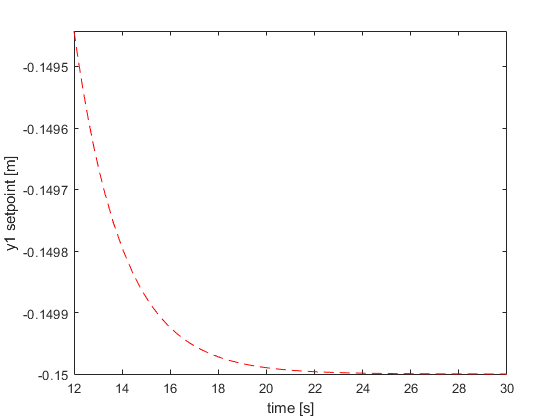

%Ideal trajectory parameters
r_sim = .15; % radius of trajectory [m] Touch screen is about 30 cm wide

%Rose curve specified by k
tot_period = 6; %this many seconds before the entire rose curve loops around 6 produced a pretty good response most recently. 5.15 for Nikon demo goes unstable
n = 2; %Selects a rose curve
d = 1; %Selects a rose curve
k = n/d; 
omega_sim = omega_rose(tot_period,n,d);

%%Rose Curve
% des_traj_sym_y1(VDefs.t) = r_sim/2*(cos((k+1)*omega_sim*VDefs.t) + cos((k-1)*omega_sim*VDefs.t));
% des_traj_sym_y2(VDefs.t) = r_sim/2*(sin((k+1)*omega_sim*VDefs.t) - sin((k-1)*omega_sim*VDefs.t));

%%Regulation
% des_traj_sym_y1(VDefs.t) = 0*VDefs.t;
% des_traj_sym_y2(VDefs.t) = 0*VDefs.t;

%%Step Response
des_traj_sym_y1(VDefs.t) = -r_sim + 0*VDefs.t;
des_traj_sym_y2(VDefs.t) = -r_sim + 0*VDefs.t;

%Specify initial conditions and compute initial outputs
x_0 = 1/2*[r_sim; 0; 0; 0; r_sim; 0; 0; 0]; %As if the ball was at rest in the center of the plate - the control objective of any regulator designed for the system

y1_0 = double(subs(out_y1_NL, [VDefs.x VDefs.beta VDefs.y VDefs.gamma],[x_0(1) x_0(3) x_0(5) x_0(7)]));
y2_0 = double(subs(out_y2_NL, [VDefs.x VDefs.beta VDefs.y VDefs.gamma],[x_0(1) x_0(3) x_0(5) x_0(7)]));


%Overlay first order smoothing functions
Tau = 2; %Time constant for first order response (3 has been working well at the 1.3 Hz)


%Trajectory symfuns with first order smoothing overlayed and a smooth transition from the
%initial conditions
des_traj_sym_y1(VDefs.t) = des_traj_sym_y1(VDefs.t)*(1-exp(-VDefs.t/Tau)) + y1_0*exp(-VDefs.t/Tau);
des_traj_sym_y2(VDefs.t) = des_traj_sym_y2(VDefs.t)*(1-exp(-VDefs.t/Tau)) + y2_0*exp(-VDefs.t/Tau);

figure
fplot(des_traj_sym_y1, 'r--') 
xlim([2*tot_period 5*tot_period]); 
ylabel('y1 setpoint [m]')
xlabel('time [s]')

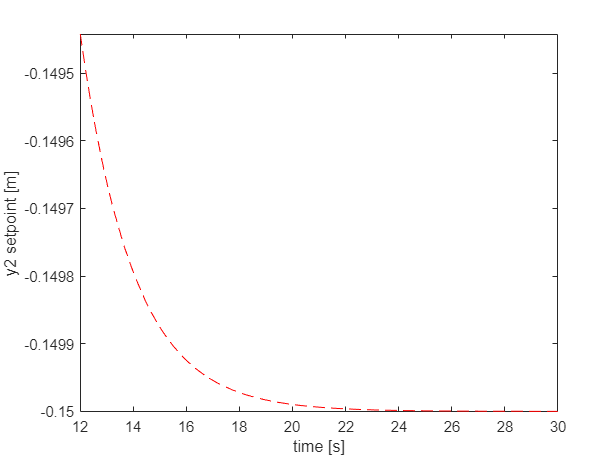


figure
fplot(des_traj_sym_y2, 'r--') 
xlim([2*tot_period 5*tot_period]); 
ylabel('y2 setpoint [m]')
xlabel('time [s]')

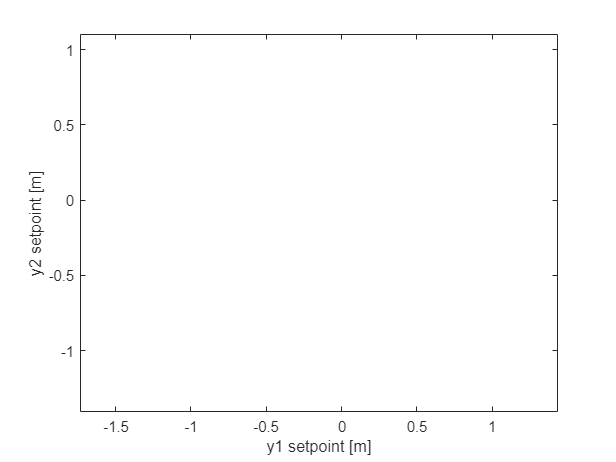


tplot = 4*tot_period:0.01:5*tot_period;
setpoint_shape = double([des_traj_sym_y1(tplot)',des_traj_sym_y2(tplot)']);
figure
plot(setpoint_shape(:,1),setpoint_shape(:,2), 'r--')
xlabel('y1 setpoint [m]')
ylabel('y2 setpoint [m]')
axis equal


%Trajectory's derivatives
des_traj_sym_dot_y1(VDefs.t) = diff(des_traj_sym_y1(VDefs.t),VDefs.t);
des_traj_sym_dot_y2(VDefs.t) = diff(des_traj_sym_y2(VDefs.t),VDefs.t);
des_traj_sym_ddot_y1(VDefs.t) = diff(des_traj_sym_y1(VDefs.t),VDefs.t,2);
des_traj_sym_ddot_y2 (VDefs.t) = diff(des_traj_sym_y2(VDefs.t),VDefs.t,2);

%x_s_vec and x_y_vec
des_traj_sym_y1 = [des_traj_sym_y1;des_traj_sym_dot_y1;des_traj_sym_ddot_y1];
des_traj_sym_y2 = [des_traj_sym_y2;des_traj_sym_dot_y2;des_traj_sym_ddot_y2];

## Numerical Control Parameters


%Choose numerical lambdas 
lambda_1_num = 1/4; %Lambda 1/4 latest working
lambda_2_num = lambda_1_num;

%Max torque
Tmax = VDefs.Tmax; % [Nm] Comes from rated torque of Scott's motors and the gear ratio assumption

%Switching gain
K_switch = Tmax/6;

%Boundary layer size
S_BL_value = 0.001; %.001 was good for 1/3 and slower trajectory frequency

%Boundary Layer Gain
BL_gain = (K_switch)/S_BL_value; %To prevent fast switches at the border of the boundary layer, need to have the cuttoff torque be equal to the switching torque
%Gain in the BL is then coupled to the size of the boundary layer. 

## Generate all the Necessary Matlab Function Blocks in Simulink

%Replace the definition of the various MATLAB function blocks with a
%function generated from symbolic functions in the dual sliding surface control
%derivations

%% System 1 MATLAB Function Blocks

% Compute global x location of ball
sim_path_string = strcat('SISO_Sliding_Mode_Control','/Controller x dimension/S1/out_y1_NL');
load_system('SISO_Sliding_Mode_Control');
input_chars = {'x' 'beta' 'y' 'gamma'};
matlabFunctionBlock(sim_path_string, out_y1_NL  , 'FunctionName', 'y1','Vars',input_chars, 'Outputs', {'y1'})

% Compute global x velocity of ball
sim_path_string = strcat('SISO_Sliding_Mode_Control','/Controller x dimension/S1/out_y1d_NL');
input_chars = {'x' 'x_dot' 'beta' 'beta_dot' 'y' 'y_dot' 'gamma' 'gamma_dot'};
matlabFunctionBlock(sim_path_string, out_y1d_NL  , 'FunctionName', 'y1d','Vars',input_chars, 'Outputs', {'y1d'})

% Compute nullifying torque T_hat_beta
sim_path_string = strcat('SISO_Sliding_Mode_Control','/Controller x dimension/Nullifying Torque');
input_chars = {'x' 'x_dot' 'beta' 'beta_dot' 'y_dot_1s' 'y_ddot_1s'};
matlabFunctionBlock(sim_path_string, subs(rhs(T_hat_beta_eqn), lambda_1, lambda_1_num)  , 'FunctionName', 'T_hat_beta','Vars',input_chars, 'Outputs', {'T_hat_beta'})

%Compute the input gain for S1dot
sim_path_string = strcat('SISO_Sliding_Mode_Control','/Controller x dimension/b_S1d');
input_chars = {'x' 'beta'};
matlabFunctionBlock(sim_path_string, b_S1d  , 'FunctionName', 'input_gain_S1d','Vars',input_chars, 'Outputs', {'b_S1d'})




% %% System 2 MATLAB Function Blocks

% Compute global y location of ball
sim_path_string = strcat('SISO_Sliding_Mode_Control','/Controller y dimension/S2/out_y2_NL');
input_chars = {'x' 'beta' 'y' 'gamma'};
matlabFunctionBlock(sim_path_string, out_y2_NL  , 'FunctionName', 'y2','Vars',input_chars, 'Outputs', {'y2'})

% Compute global x velocity of ball
sim_path_string = strcat('SISO_Sliding_Mode_Control','/Controller y dimension/S2/out_y2d_NL');
input_chars = {'x' 'x_dot' 'beta' 'beta_dot' 'y' 'y_dot' 'gamma' 'gamma_dot'};
matlabFunctionBlock(sim_path_string, out_y2d_NL  , 'FunctionName', 'y2d','Vars',input_chars, 'Outputs', {'y2d'})

% Compute nullifying torque T_hat_gamma
sim_path_string = strcat('SISO_Sliding_Mode_Control','/Controller y dimension/Nullifying Torque');
input_chars = {'y' 'y_dot' 'gamma' 'gamma_dot' 'y_dot_2s' 'y_ddot_2s'};
matlabFunctionBlock(sim_path_string, subs(rhs(T_hat_gamma_eqn), lambda_2, lambda_2_num)  , 'FunctionName', 'T_hat_gamma','Vars',input_chars, 'Outputs', {'T_hat_gamma'})

%Compute the input gain for S2dot
sim_path_string = strcat('SISO_Sliding_Mode_Control','/Controller y dimension/b_S2d');
input_chars = {'y' 'gamma'};
matlabFunctionBlock(sim_path_string, b_S2d  , 'FunctionName', 'input_gain_S2d','Vars',input_chars, 'Outputs', {'b_S2d'})



%%Trajectory Setpoints 

%x direction
sim_path_string = strcat('SISO_Sliding_Mode_Control','/Setpoint_Vectors/global_x_Setpoint_Function');
matlabFunctionBlock(sim_path_string, des_traj_sym_y1,'FunctionName', 'y1_s_vec')

%y direction
sim_path_string = strcat('SISO_Sliding_Mode_Control','/Setpoint_Vectors/global_y_Setpoint_Function');
matlabFunctionBlock(sim_path_string, des_traj_sym_y2,'FunctionName', 'y2_s_vec')

%Replace the definition of the "Plant_Function" MATLAB function block with a
%function generated from obj.plant symbolic function
sim_path_string = strcat('SISO_Sliding_Mode_Control','/Plant/Plant_Function');
%Generate a matlab function from the linearized plant model
input_chars = {'x', 'x_dot', 'beta', 'beta_dot','y', 'y_dot', 'gamma', 'gamma_dot', 'T_beta', 'T_gamma' };
matlabFunctionBlock(sim_path_string, rhs(BP_Kinetics.NL_NumEOMs), 'FunctionName', 'xdot','Vars',input_chars)


## Simulate the Output Sliding Mode Controller

%Specify simulation time
tspan = [0 tot_period*3]; %tot_period*3

simout_SISO_SM = sim('SISO_Sliding_Mode_Control')

simout_SISO_SM =   Simulink.SimulationOutput:

                     S1: [4677x1 double] 
                     S2: [4677x1 double] 
                   tout: [4677x1 double] 
                      u: [4677x2 double] 
                      x: [4677x8 double] 
                     y1: [4677x1 double] 
               y1_s_vec: [4677x3 double] 
                     y2: [4677x1 double] 
               y2_s_vec: [4677x3 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


## Plot some stuff

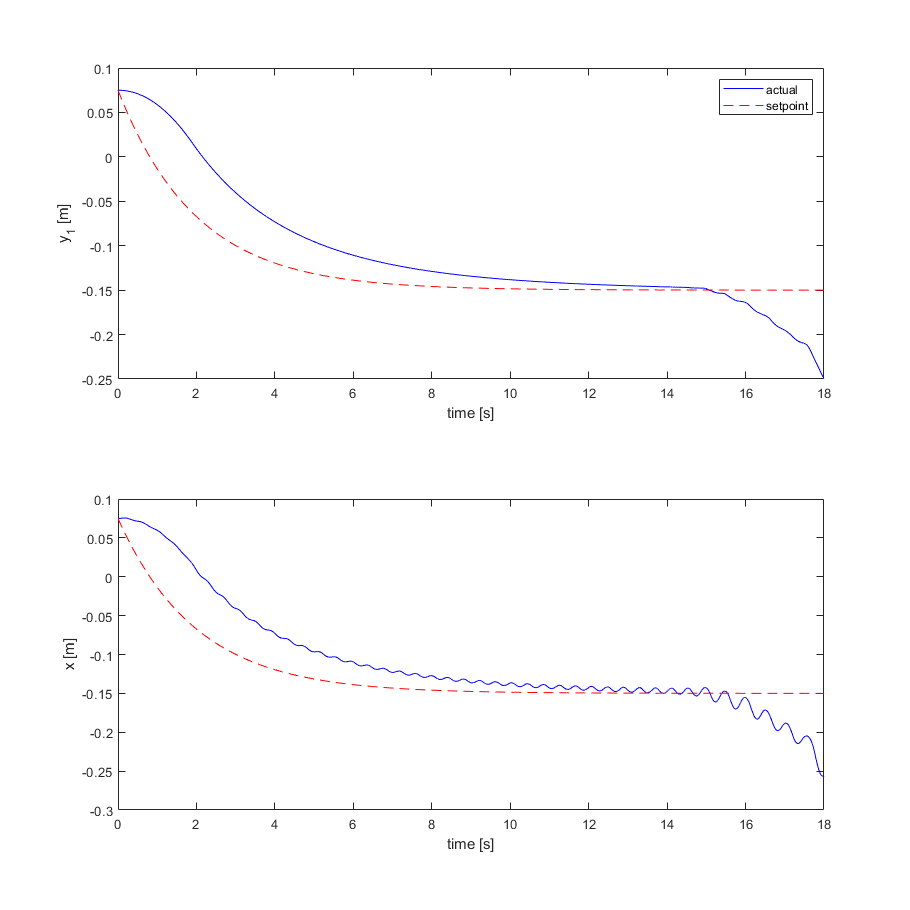

figure
ax1 = subplot(2,1,1);
plot(simout_SISO_SM.tout,simout_SISO_SM.y1,'b',simout_SISO_SM.tout,simout_SISO_SM.y1_s_vec(:,1),'--r')  
xlabel('time [s]')
ylabel('y_1 [m]')
legend('actual', 'setpoint')

ax2 = subplot(2,1,2);
plot(simout_SISO_SM.tout,simout_SISO_SM.x(:,1),'b',simout_SISO_SM.tout,simout_SISO_SM.y1_s_vec(:,1),'--r' )
xlabel('time [s]')
ylabel('x [m]')


linkaxes([ax1,ax2],'x');
set(gcf,'position',[0,0,1200,1200]);

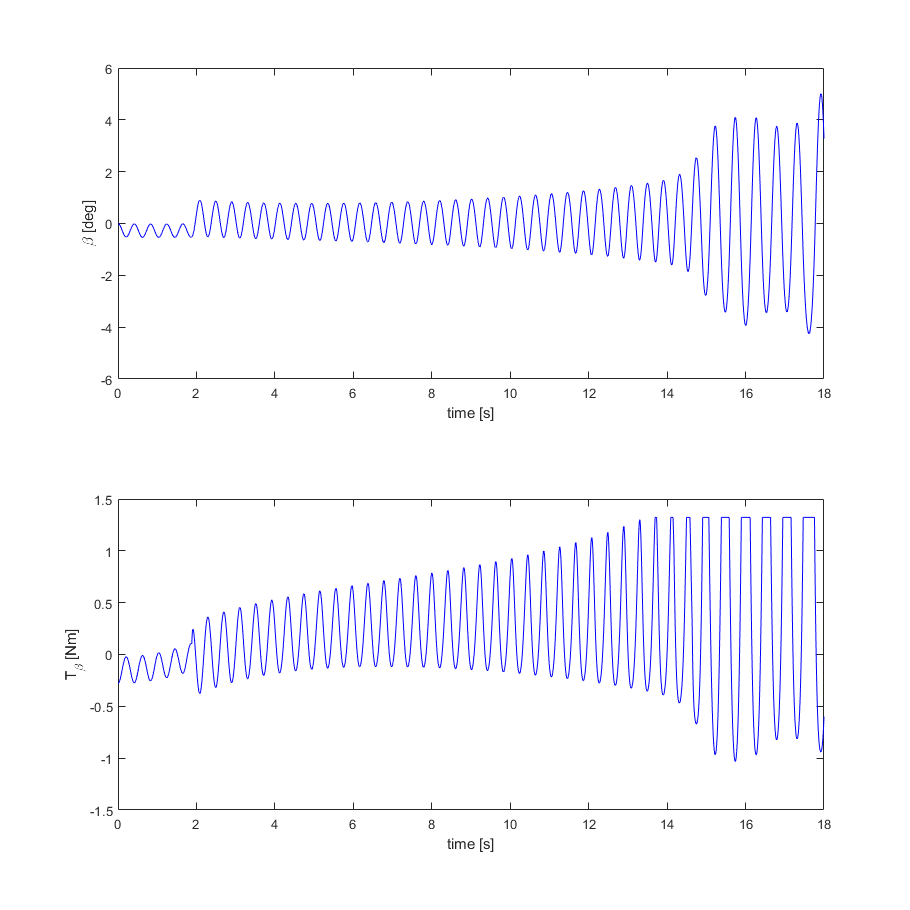


figure
ax1 = subplot(2,1,1);
plot(simout_SISO_SM.tout,rad2deg(simout_SISO_SM.x(:,3)),'b')
xlabel('time [s]')
ylabel('\beta [deg]')


ax2 = subplot(2,1,2);
plot(simout_SISO_SM.tout,simout_SISO_SM.u(:,1),'b')
xlabel('time [s]')
ylabel('T_{\beta} [Nm]')

% ax3 = subplot(3,1,3);
% plot(simout_SISO_SM.tout,(simout_SISO_SM.y1_s_vec(:,1) - simout_SISO_SM.y1(:,1)),'b')
% xlabel('time [s]')
% ylabel('error in y1 [m]')


linkaxes([ax1,ax2],'x');
set(gcf,'position',[0,0,1200,1200]);

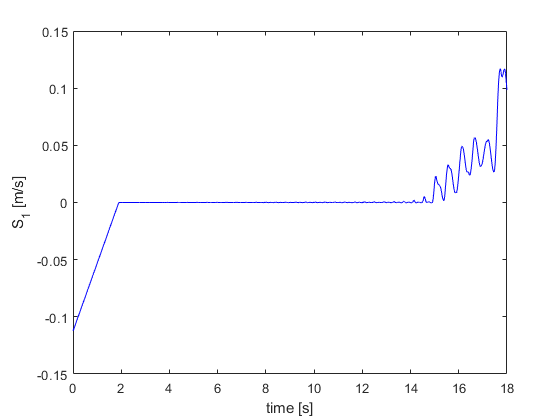


figure
plot(simout_SISO_SM.tout, simout_SISO_SM.S1,'b')
xlabel('time [s]')
ylabel('S_1 [m/s]')

### Animate Responses

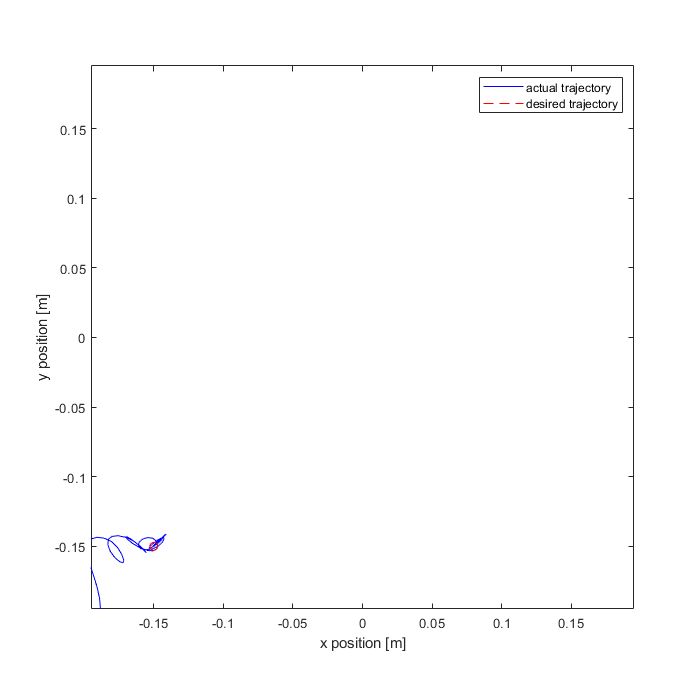

i_plot = simout_SISO_SM.tout>=2*tot_period & simout_SISO_SM.tout<=3*tot_period; %Indices associated with the times to plot
t_window = tot_period;
fps = 25;
Animate_Response(simout_SISO_SM.x(i_plot,1),simout_SISO_SM.y1_s_vec(i_plot,1),...
     simout_SISO_SM.x(i_plot,5),simout_SISO_SM.y2_s_vec(i_plot,1),simout_SISO_SM.tout(i_plot),fps,'SISO_SM_States.gif', r_sim, t_window)

Animate_Response(simout_SISO_SM.y1(i_plot),simout_SISO_SM.y1_s_vec(i_plot,1),...
     simout_SISO_SM.y2(i_plot),simout_SISO_SM.y2_s_vec(i_plot,1),simout_SISO_SM.tout(i_plot),25,'SISO_SM_Output.gif', r_sim, tot_period)

view_vec = [140+180 40];
Animate_Response_3D(simout_SISO_SM.x(i_plot,:),simout_SISO_SM.tout(i_plot),25,'SISO_SM_3D.gif',VDefs, view_vec, setpoint_shape)

function [num_thing] = Num_Params(thing, VDefs)
    %Num_ParamsInput estimated numerical parameters of the system
        %   Detailed explanation goes here
        
    
        %Numerical Parameters in terms of symbolic variables utilized in 
        %the model 
        Num_Params = [VDefs.rB  (VDefs.rC+VDefs.rB) ...
        VDefs.mB VDefs.mP VDefs.IP VDefs.IB ...
        VDefs.g_num VDefs.rG];
    
        Sym_Params = [VDefs.r_b VDefs.z_b VDefs.m_b...
            VDefs.m_p VDefs.I_p_xx VDefs.I_b VDefs.g...
            VDefs.z_p];
        
        
        %Substitute in all numerical parameters and assumptions
        num_thing = subs(thing, Sym_Params,Num_Params);
            
end